clc;
close all;
clear all;
load mgdata.dat
a = mgdata;
x=a(:,2)'

x =     1.2000    1.0858    0.9825    0.8890    0.8044    0.7278    0.6586    0.5959    0.5392    0.4879    0.4415    0.3994    0.3614    0.3270    0.2959    0.2678    0.2423    0.2192    0.2465    0.3078    0.3972    0.4947    0.5833    0.6556    0.7107    0.7500    0.7756    0.7896    0.7940    0.7903    0.7802    0.7648    0.7453    0.7226    0.6975    0.6752    0.6639    0.6685    0.6908    0.7286    0.7771    0.8309    0.8854    0.9374    0.9854    1.0290    1.0685    1.1040    1.1356    1.1630


Training=x(1,1:950)       % Selecting a Interval of series data t = 1to 950

Training =     1.2000    1.0858    0.9825    0.8890    0.8044    0.7278    0.6586    0.5959    0.5392    0.4879    0.4415    0.3994    0.3614    0.3270    0.2959    0.2678    0.2423    0.2192    0.2465    0.3078    0.3972    0.4947    0.5833    0.6556    0.7107    0.7500    0.7756    0.7896    0.7940    0.7903    0.7802    0.7648    0.7453    0.7226    0.6975    0.6752    0.6639    0.6685    0.6908    0.7286    0.7771    0.8309    0.8854    0.9374    0.9854    1.0290    1.0685    1.1040    1.1356    1.1630


Yr=Training;
% For testing
Test=x(1,951:1200)

Test =     1.1477    1.1632    1.1772    1.1912    1.2064    1.2234    1.2417    1.2604    1.2778    1.2916    1.2985    1.2948    1.2769    1.2444    1.1995    1.1468    1.0902    1.0327    0.9761    0.9213    0.8686    0.8178    0.7687    0.7212    0.6753    0.6313    0.5896    0.5506    0.5152    0.4845    0.4601    0.4443    0.4404    0.4520    0.4821    0.5309    0.5948    0.6667    0.7391    0.8059    0.8636    0.9103    0.9458    0.9706    0.9859    0.9929    0.9930    0.9880    0.9797    0.9703


Ys=Training;
time_steps=5;
mu=0.005;       % step size 
M=1;            % Order of LMS filter

U=zeros(M+1,1); % Initial values of taps
W=zeros(M+1,1); % Initial weight of LMS
teacher_forcing=5;
MSE=[];         % Initial mean squared error (MSE)
z=[];
E=[];
tic % start
for t=1:950-time_steps
    U(1:end-1)=U(2:end);                 % Shifting of tap window

    if (teacher_forcing==1)
        if rem(t,time_steps)==0 || (t==Training(1))
            U(end)=Yr(t);                  % Input (past/current samples)
        else
            U(end)=Yp(t-1);                % Input (past/current samples)
        end
    else
        U(end)=Yr(t);                      % Input (past/current samples)
    end

    Yp(t)=W'*U;                             % Predicted output
    e(t)=Yr(t+time_steps)-Yp(t);            % Error in predicted output

    W=W+mu*e(t)*U;                          % Weight update rule of LMS
    se(t)=e(t).^2;                          % Current mean squared error (MSE)
end
training_time=toc                           % total time including training and calculation of MSE

training_time = 0.0080

%for testing 
tic % start
U=U*0;                              % Reinitialization of taps (optional)
for t=1:length(Test)-time_steps+1
    U(1:end-1)=U(2:end);            % Shifting of tap window

    if (teacher_forcing==1)
        if rem(t,time_steps)==0 || (t==Test(1))
            U(end)=Ys(t);           % Input (past/current samples)
        else
            U(end)=Yp(t-1);         % Input (past/current samples)
        end
    else
        U(end)=Ys(t);               % Input (past/current samples)
    end


    Yp1(t)=W'*U;                     % Calculating output (future value)
    e(t)=Ys(t+time_steps-1)-Yp1(t);  % Error in predicted output

    se1(t)=e(t).^2;                  % Current mean squared error (MSE)
end
testing_time=toc                    % total time including testing and calculation of MSE

testing_time = 0.0083

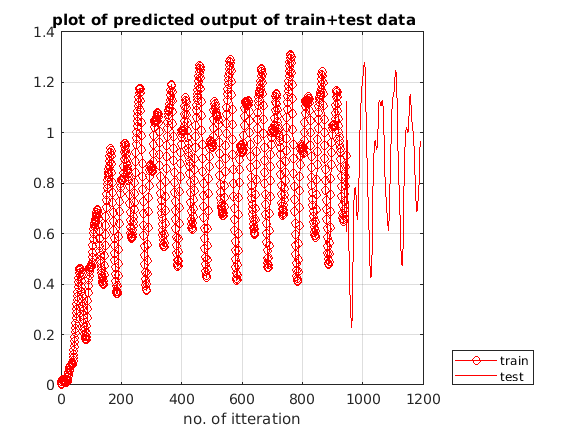

figure 
z=[z,Yp];
plot(Yp,'r-o');
grid on ;
hold on;

z=[z,Yp1];
plot(z,'r');
xlabel('no. of itteration');
title('plot of predicted output of train+test data   ');
grid on ;
legend('train','test', "Location","southeastoutside")

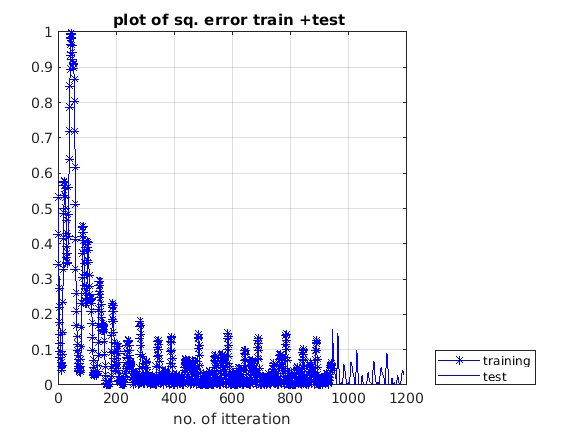



figure 
E=[E,se];
plot(se,'b-*');
xlabel('no. of itteration');
title('plot of sq. error  ');
grid on ;
hold on ;
E=[E,se1];
plot(E,'b')
xlabel('no. of itteration');
title('plot of sq. error train +test ');
legend('training','test' , "Location","southeastoutside");

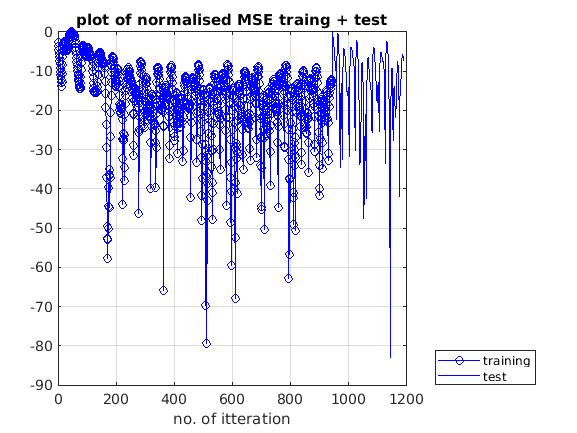

figure 
Z=[];
nmse=se/max(se);
Z=[Z,nmse];
plot(10*log10(Z),'b-o');
grid on ;
hold on ;
nmse1=se1/max(se1);
Z=[Z,nmse1];

plot(10*log10(Z),' b-');

title('plot of normalised MSE traing + test');
xlabel('no. of itteration');
legend('training','test' , "Location","southeastoutside");% test graph should be from 945 to 1200 but i coudnt able to do it 